%EE 451 Midterm Exam
%Lisa Jacklin
% 10/20/2023


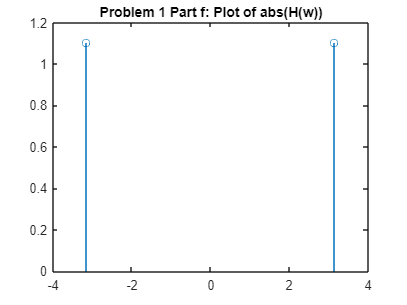


%Problem 1 Part f: Plot abs(H(w)) for -pi < w < pi
w = [-pi pi];
H = ((exp(-1i*w)).^2 + 1) ./ ((exp(-j*w)).^2 + 0.81);
stem(w, abs(H));
title('Problem 1 Part f: Plot of abs(H(w))');


%problem 1 part i: give the filter coefficients [a] and [b] for the filter
a = [1 1];
b = [1 0.81];
%please note that these can also be seen in my hand written notes

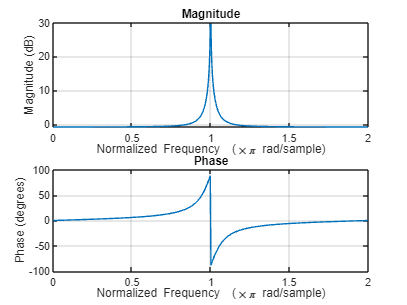

%problem 1 part j
Fs = 1000; %sampling frequency is given

%note that since we are given the coefficients of the filter, we can put
%them into freqz along with 'whole' for a filled line and Fs for the
%smapling frequency to obtain the frequency response.
freqz(b,a, 'whole', Fs);

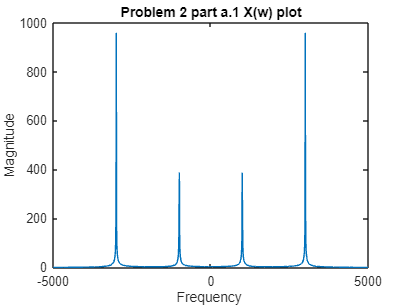

%Problem 2 Part a
%part a.1
%please note that all hand calculations are on page 3 of my physical
%submission.
Fs2 = 10000; %given sampling of 10kHz
Ts2 = 1/Fs2; 
N = 1024; %sample size by assumption
n = 0:1023;

xn = cos(pi .* n/5) + 2*cos((3*pi.*n)/5); %discrete version of x(n)
XW = fftshift(fft(xn)); %fftshift and fft are used to obtain the frequency version!
F = -Fs2/2:Fs2/(N-1):Fs2/2;
plot(F, abs(XW));
title("Problem 2 part a.1 X(w) plot");
xlabel("Frequency "); ylabel("Magnitude");

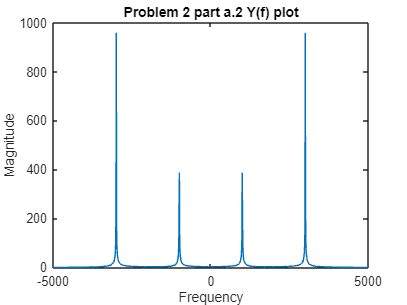


%part a.2
%plot Y(f) for y(t) given that the channel doesn't cause distortion and the
%gain is 1 so no changes made to the signal.
t = 0:Ts2:(N-1)*Ts2;

yt = cos(2*pi*1000*t) + 2*cos(2*pi*3000*t); %y(t)
YF = fftshift(fft(yt));
plot(F, abs(YF));
title("Problem 2 part a.2 Y(f) plot");
xlabel("Frequency"); ylabel("Magnitude");

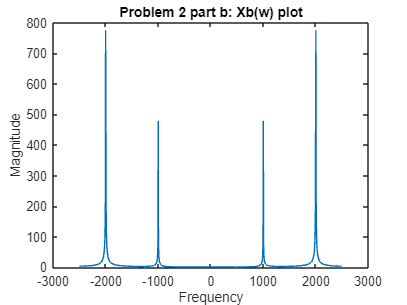

%Problem 2 Part b
%part b.1
Fs2b = 5000; %frequency sampling at 5kHz
Ts2b = 1/Fs2b;
N = 1024; %assumed sampling
n = 0:1023; 

xnb = cos((pi.* 2*n)/5) + 2*cos((6*pi.*n)/5);
XWb = fftshift(fft(xnb));
Fb = -Fs2b/2:Fs2b/(N-1):Fs2b/2;
plot(Fb, abs(XWb));
title("Problem 2 part b: Xb(w) plot");
xlabel("Frequency"); ylabel("Magnitude");

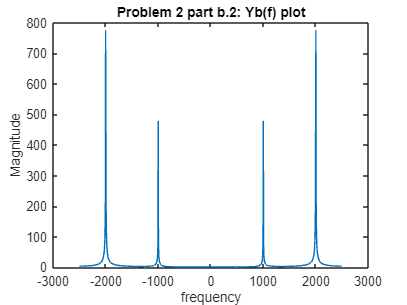


%part b.2
t2 = 0:Ts2b:(N-1)*Ts2b;

yt2 = cos(2*pi*1000*t2) + 2 *cos(2*pi*3000*t2); %yb(t)
YF2 = fftshift(fft(yt2));
plot(Fb, abs(YF2));
title("Problem 2 part b.2: Yb(f) plot");
xlabel("frequency"); ylabel("Magnitude");